# Algoritmo PBILL para un inversor

clear; clc; close all;
rng('shuffle'); %Cambiar la semilla

## Parametros

N = 30; %Tamañano de la población
iter    = 0;
stall = 0;
LR = 0.01; %Learning Rule fija
tol = 1e-9;
Max_iter = 1000; %Max Iter
Max_stall = 200; %Stall condition
P = 0.5*ones(1,1000); %Vector de probabilidad neutra
Best_total = Inf; %Mejor costo encontrado de todas las gen
Best_ind = zeros(1, 1000); %Mejor individuo encontrado de todas las gen
hist_Best    = zeros(1, Max_iter);
histLR      = zeros(1, Max_iter); 

## Algoritmo

while iter < Max_iter && stall < Max_stall
    iter = iter + 1; %Actuliza el numero del ciclo

    A = rand(N, 1000); %Población ajustada por Probabilidad
    for i=1:N
        for j=1:length(P)
            if A(i,j) < P(j)
                A(i,j) = 1;
            else
                A(i,j) = 0;
            end
        end
    end

    costo = zeros(1,N); 
    for i=1:N
        costo(i) = pwm_sin(A(i,:));%Costo de la generación
    end

    %Mejor de la generación
    [Best, pos] = min(costo); %Mejor costo
    Best_Gen = A(pos,:); %Mejor individuo

    %Stall condition
    if Best < Best_total*(1-tol)
        stall = 0;
    else 
        stall = stall +1;
    end

    %Actualizar el mejor
    if Best < Best_total
        Best_total = Best;
        Best_ind = Best_Gen;
    end

    b = (Best_Gen == 1);
    P(b) = P(b).* (1+LR);
    P(~b) = P(~b).*(1-LR);
    P(P>1) = 1;
    P(P<0) = 0;

    %Actualizar el mejor
    hist_Best(iter) = Best_total;
          
end


## Graficas y resultados

hist_Best = hist_Best(1:iter);
if iter >= Max_iter
    motivo = 'iteraciones maximas';
elseif stall >= Max_stall
    motivo = sprintf('stall condition (%d iteraciones sin mejora)', Max_stall);
end

fprintf('\n RESULTADOS PBIL \n');


 RESULTADOS PBIL 


fprintf('Mejor costo (THD) encontrado: %.6f\n', Best_total);

Mejor costo (THD) encontrado: 0.000824


fprintf('Iteraciones realizadas: %d de %d\n', iter, Max_iter);

Iteraciones realizadas: 497 de 1000


fprintf('Motivo de parada: %s\n', motivo);

Motivo de parada: stall condition (200 iteraciones sin mejora)


fprintf('Parametros: N = %d, LR = %.3f\n', N, LR);

Parametros: N = 30, LR = 0.010


fprintf('Posiciones en 1: %d de 1000 (%.1f %%)\n', sum(Best_ind), 100*mean(Best_ind));

Posiciones en 1: 565 de 1000 (56.5 %)


fprintf('Mejor patron encontrado:\n');

Mejor patron encontrado:


disp(Best_ind);

     0     1     1     1     0     1     0     0     0     0     0     0     1     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     1     0     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     1     1     0     0     0     0     1     0     0     1     0     0     0     0     1     0     1     0     0     1     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     1     0     0     0     1     0     0     0     1     0     0     0     0     0     0     0     1     1     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     1     1     0     0     0     0     1     0     0     1     1     1     1     1     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     1     1     1     1     1     0     0     0     0     0     0     0     0    

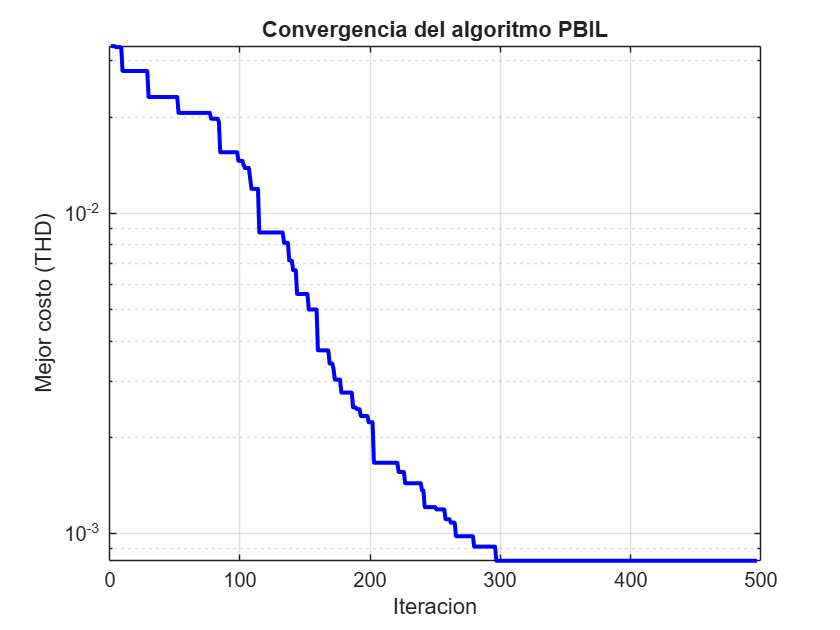


%% Convergencia del algoritmo 
figure;
semilogy(1:iter, hist_Best, 'b', 'LineWidth', 2);
xlabel('Iteracion');
ylabel('Mejor costo (THD)');
title('Convergencia del algoritmo PBIL');
grid on;

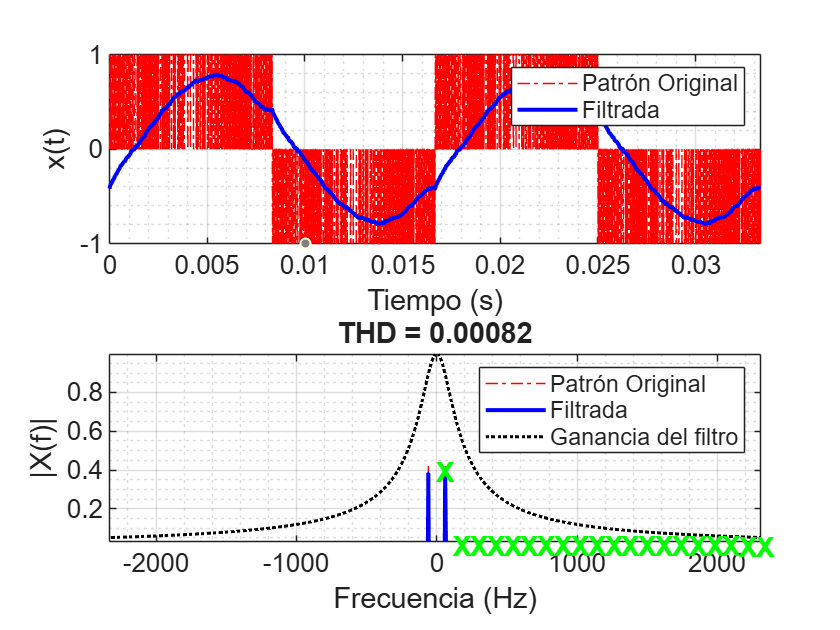



%% Resultado
figure; pwm_sin_g(Best_ind);